## Simulation variables

clear;
chan = "NoImpairments";
SNRdB = 40;
frames = 1;
brspace = 2;
totalNoSlots = frames*10;          % Number slots containing information simulated

## Set 5G  variables

 [carrier, pdsch, NHARQProcesses, rvSeq, codeRate, encodeDLSCH, decodeDLSCH] = genvar5g

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: false
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: false
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: false
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: false
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel config

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-E";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;

## Constellation plot setup

constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements


% Setup Spectrum viewer
spectrumScope = spectrumAnalyzer( ...
    SpectrumType='power-density', ...
    Title='Received Baseband 5G NR Signal Spectrum', ...
    YLabel='Power spectral density', ...
    Position=[69 376 800 450]);

## Variables

% Initial timing offset
offset = 0;

% Wave varible
longwave = 0.00001+0.00001i;

% Generate PDSCH indices info, which is needed to calculate the transport
% block size
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

% Calculate transport block sizes
Xoh_PDSCH = 0;
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschInfo.NREPerPRB,codeRate,Xoh_PDSCH);

estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

## SDR setup

tx = comm.SDRuTransmitter(...
               Platform = "B200", ...
              SerialNum = "3293CEA", ...
              CenterFrequency = 2400000000, ...
              InterpolationFactor = 256, ...
              MasterClockRate = channel.SampleRate, ...
              Gain = 20);

rx = comm.SDRuReceiver(...
              Platform ="B200", ...
              SerialNum ="3293CEA", ...
              CenterFrequency =2400000000, ...
              MasterClockRate =channel.SampleRate, ...
              DecimationFactor = 256, ...
              OutputDataType = 'double' );
rx.Gain = 70;
rx.EnableBurstMode = false;

% Provide trigger time
usrpTriggerTime = 4;

tx.EnableTimeTrigger = true;
tx.TriggerTime = usrpTriggerTime;

## Wave generation

totbrak = 0;
makebrake = 0;
for nSlot = 0:totalNoSlots-1
    carrier.NSlot = nSlot;

    data = randi([0 1],trBlkSizes,1);
    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity2(carrier, pdsch, encodeDLSCH, harqEntity, newPrecodingWeight, codeRate, data, nTxAnts, decodeDLSCH);

    makebrake = makebrake + 1;
    if makebrake >= 10
        brake = 15360*brspace;%chInfo.MaximumChannelDelay;
        totbrak = totbrak + 1;
        makebrake = 0;
    else
        brake = 0;
    end


    txWaveform = [txWaveform; zeros(brake,size(txWaveform,2))];

    if strcmpi(chan,"OverTheAir")
        longwave = cat(1, longwave,txWaveform);
    elseif strcmpi(chan,"GaussianNoise")
        [txWaveform2,pathGains,sampleTimes] = channel(txWaveform);
        noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(txWaveform2));
        txWaveform2 = txWaveform2 + noise;
        longwave = cat(1, longwave,txWaveform2);
    else
        longwave = cat(1, longwave,txWaveform);
    end
end  

## Wave transmison

if strcmpi(chan,"OverTheAir")
   tx(longwave);
else
   chInfo = info(channel);
   maxChDelay = 20000;%chInfo.MaximumChannelDelay;
   longwave = [zeros(maxChDelay,size(longwave,2));longwave; zeros(maxChDelay,size(longwave,2))];
end

## Wave capture

if strcmpi(chan,"OverTheAir")
   rxWaveform2 = capture(rx,4,'seconds');
else
   rxWaveform2 = longwave;
end

## Wave offset removal

rxWaveform = rxWaveform2;
precodingWeights = newPrecodingWeight;
dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
[pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);

%% Timing Synchronization
[t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
offset = hSkipWeakTimingOffset(offset,t,mag);

   
pakoff = ((totalNoSlots*15360)-15360+((frames-1)*15360*brspace));
pakoff2 = 9*15360;

if offset >= pakoff
   rxWaveform = rxWaveform(1+offset-pakoff:end,:);
elseif offset >= pakoff2
   rxWaveform = rxWaveform(1+offset-pakoff2:end,:);
else
   rxWaveform = rxWaveform(1+offset:end,:);
end
    

## Wave decoding

stframe = 1;
wavelength = size(rxWaveform,1) 

wavelength = 1863193

nframes = 1

nSlot = 0

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 1

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 2

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 3

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 4

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 5

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 6

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 7

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 8

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 9

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 2

nSlot = 10

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 11

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 12

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 13

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 14

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 15

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 16

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 17

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 18

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 19

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 3

nSlot = 20

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 21

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 22

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 23

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 24

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 25

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 26

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 27

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 28

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 29

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 4

nSlot = 30

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 31

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 32

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 33

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 34

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 35

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 36

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 37

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 38

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 39

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 5

nSlot = 40

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 41

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 42

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 43

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 44

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 45

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 46

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 47

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 48

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 49

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 6

nSlot = 50

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 51

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 52

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 53

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 54

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 55

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 56

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 57

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 58

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 59

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 7

nSlot = 60

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 61

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 62

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 63

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 64

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 65

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 66

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 67

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 68

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 69

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 8

nSlot = 70

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 71

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 72

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 73

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 74

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 75

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 76

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 77

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 78

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 79

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 9

nSlot = 80

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 81

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 82

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 83

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 84

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 85

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 86

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 87

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 88

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 89

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nframes = 10

nSlot = 90

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 91

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 92

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 93

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 94

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 95

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 96

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 97

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 98

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

nSlot = 99

statusReport = "HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900)."

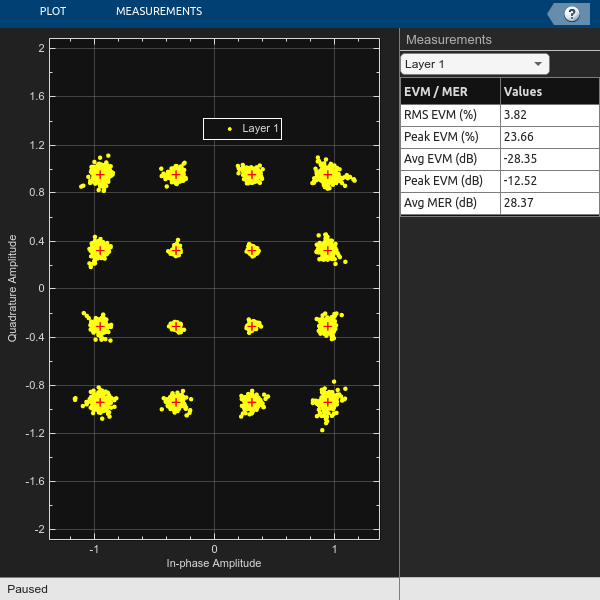

enframe = 15500*11;
if enframe >= (wavelength - stframe)
   enframe = wavelength;
end

framebrake = 0;
offset2 = 0;
frslot = 0;
decslots = 10;

for nframes = 1:frames
    nframes
    frawave = rxWaveform(stframe:enframe,1);


    [t2,mag2] = nrTimingEstimate(carrier,frawave,dmrsIndices,dmrsSymbols);
    offset2 = hSkipWeakTimingOffset(offset2,t2,mag2);
   
    if offset2 >= pakoff2
        frawave = frawave(1+offset2-pakoff2:end,:);
    else
        frawave = frawave(1+offset2:end,:);
    end
    

    srec = 1;
    erec = 15360;
    for nSlot = frslot:decslots-1
        carrier.NSlot = nSlot;
        nSlot
        decWave = frawave(srec:erec,1);
        
        srec = srec + 15360;
        erec = erec + 15360;

        % Slot decoding
        [decbits, statusReport, pdschEq] = RecieverEntity2(carrier, pdsch, decodeDLSCH, harqEntity, decWave, 0, newPrecodingWeight, trBlkSizes);
        decbits;
        statusReport

        constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
        constPlot.ShowLegend = true;
        % Constellation for the first layer has a higher SNR than that for the
        % last layer. Flip the layers so that the constellations do not mask
        % each other.
        constPlot(fliplr(pdschEq));


    end
    stframe = stframe + 15360*(10+brspace);
    

    if enframe >= (wavelength - stframe)
        enframe = wavelength;
    else
        enframe = enframe + 15360*(10+brspace);
    end

    frslot = nSlot+1;
    decslots = decslots + 10;
end

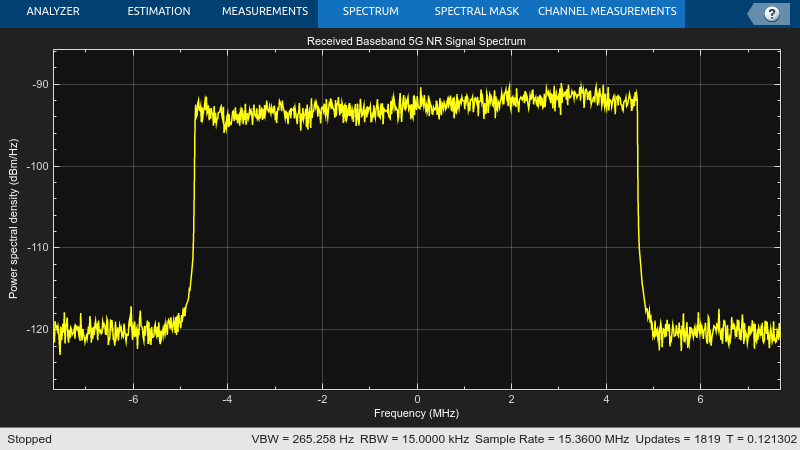


spectrumScope.SampleRate = channel.SampleRate;
spectrumScope(rxWaveform);
release(spectrumScope);

## SDR release

release(tx);
fprintf('Recieving stopped.\n')

Recieving stopped.


release(rx);
fprintf('Transmission stopped.\n')

Transmission stopped.


## Local Functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end
